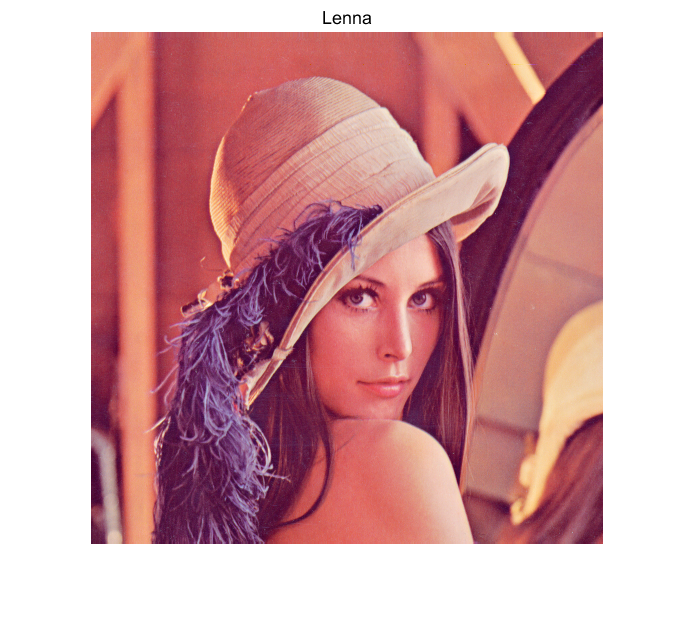

% 读取、显示Lenna.png
im = imread('Lenna.png');
imshow(im)
title('Lenna')

% 使用help imresize命令查看用法
help imresize

imresize - 调整图像大小

    此 MATLAB 函数 返回图像 B，它是将 A 的长宽大小缩放 scale 倍之后的图像。输入图像 A 可以是灰度、RGB 或二进制图像。如果 A
    有两个以上维度，则 imresize 只调整前两个维度的大小。如果 scale 在 [0, 1] 范围内，则 B 比 A 小。如果 scale 大于 1，则 B
    比 A 大。默认情况下，imresize 使用双三次方插值。

    B = imresize(A,scale)
    B = imresize(A,[numrows numcols])
    [Y,newmap] = imresize(X,map,___)
    ___ = imresize(___,method)
    ___ = imresize(___,Name,Value)

    另请参阅 <a href="https://www.mathworks.com/help/releases/R2018a/images/ref/imresize3.html">imresize3</a>, <a href="https://www.mathworks.com/help/releases/R2018a/images/ref/imrotate.html">imrotate</a>, <a href="https://www.mathworks.com/help/releases/R2018a/images/ref/imtransform.html">imtransform</a>, <a href="https://www.mathworks.com/help/releases/R2018a/matlab/ref/interp2.html">interp2</a>, <a href="https://www.mathworks.com/help/releases/R2018a/images/ref/tformarray.html">tformarray</a>

    imresize 的参考页



% 将Lenna.png放大3倍，存储为Lenna3.png
im3 = imresize(im, 3);
imshow(im3)

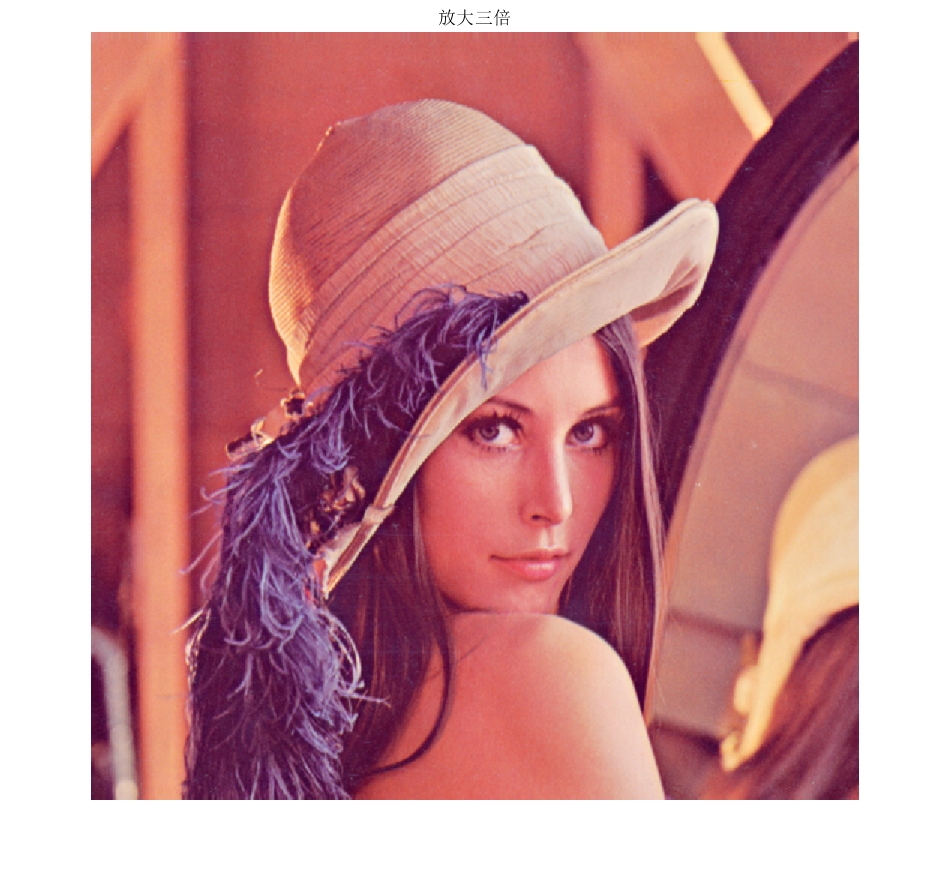

title('放大三倍')
saveas(gcf, 'Lenna3.png')

% 将Lenna.png向左平移两个像素，存储为Lenna2.png
[~, col_1, ~] = size(im);
im2 = im(:, 3:col——1, :);
[~, col_2, ~] = size(im2);
sprintf('平移前宽度为%d,平移后宽度为%d', col_1, col_2)

ans = '平移前宽度为512,平移后宽度为508'

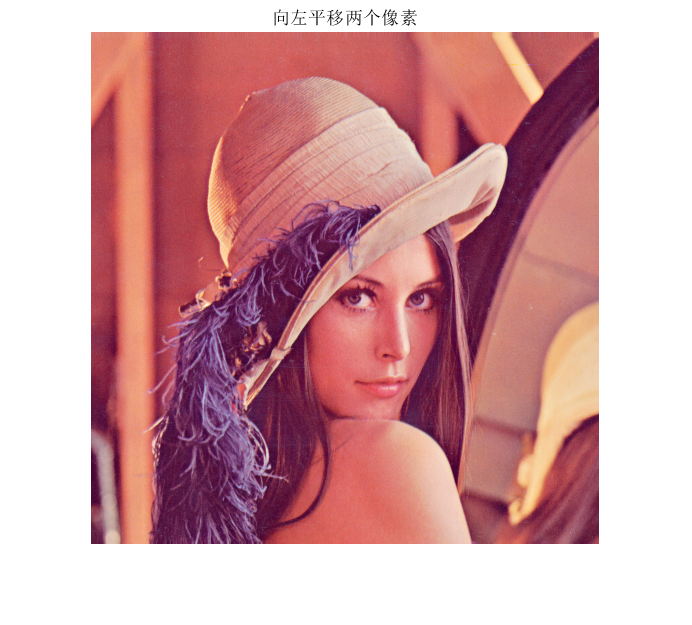

imshow(im2)
title('向左平移两个像素')
saveas(gcf, 'Lenna2.jpg')